clear all 
format long

q = 10 ;

R = 0.2:0.001:0.8 ;

M = length(R);

for j = 1:M 
    r = R(j);
    y = roots([r  -r*q q+r -r*q]);
    n = length(y);
    hold on 
    for k = 1:n
        if imag(y(k)) == 0 && real(y(k)) >= 0
            plot(r,y(k),'b.','MarkerSize',20);
        end
    end
end

now we seee stablilty aspects to check the sign of fdot x

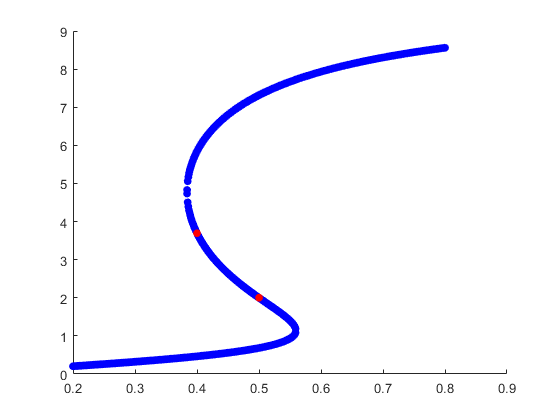

clear all 
format long

q = 10 ;

R = 0.2:0.1:0.8 ;

M = length(R);

for j = 1:M 
    r = R(j);
    y = roots([r  -r*q q+r -r*q]);
    n = length(y);
    hold on 
    for k = 1:n
        if imag(y(k)) == 0 && real(y(k)) >= 0
            D = r*(1-2*y(k)/q) -2*y(k)/(1+y(k)^2) +2*y(k)^3/(1+y(k)^2)^2 ; %derivative
            if D<0 
                plot(r,y(k),'b.','MarkerSize',20);
            elseif D> 0 
                plot(r,y(k),'r.','MarkerSize',20);
            else
                plot(r,y(k),'m.','MarkerSize',20);
            end
            
        end
    end
end